clear;close all;clc
syms t I A T epsilon lambda n

D(t) = -(2*pi/lambda)*I^(2)*sin((2*pi/lambda).*A*(2*cos((2*pi/T)*(t-epsilon/2)).*sin(pi*epsilon/T)))*n*lambda;
D(t) = (2*pi/lambda)*I^(2)*sin((2*pi/lambda).*A*(sin((2*pi/T)*(t-epsilon/2)) - sin(t*pi*epsilon/T)))*n*lambda;
D(t) = (2*pi/lambda)*I^(2)*sin((2*pi/lambda)*A*(sin((2*pi/T)*(t-epsilon)) - sin((2*pi/T)*t)))*n*lambda

$$D(t) = -2\,\pi \,{\text{I}}^{2}\,n\,\sin\left(\frac{2\,\pi \,A\,\left(\sin\left(\frac{2\,\pi \,t}{T}\right)+\sin\left(\frac{2\,\pi \,\left(\epsilon -t\right)}{T}\right)\right)}{\lambda }\right)$$

DD =  @(t, I, A, T, epsilon, lambda, n) (2*pi/lambda)*I^(2)*sin((2*pi/lambda)*A*(sin((2*pi/T)*(t-epsilon)) - sin((2*pi/T)*t)))*n*lambda

DD = function_handle with value:
    @(t,I,A,T,epsilon,lambda,n)(2*pi/lambda)*I^(2)*sin((2*pi/lambda)*A*(sin((2*pi/T)*(t-epsilon))-sin((2*pi/T)*t)))*n*lambda


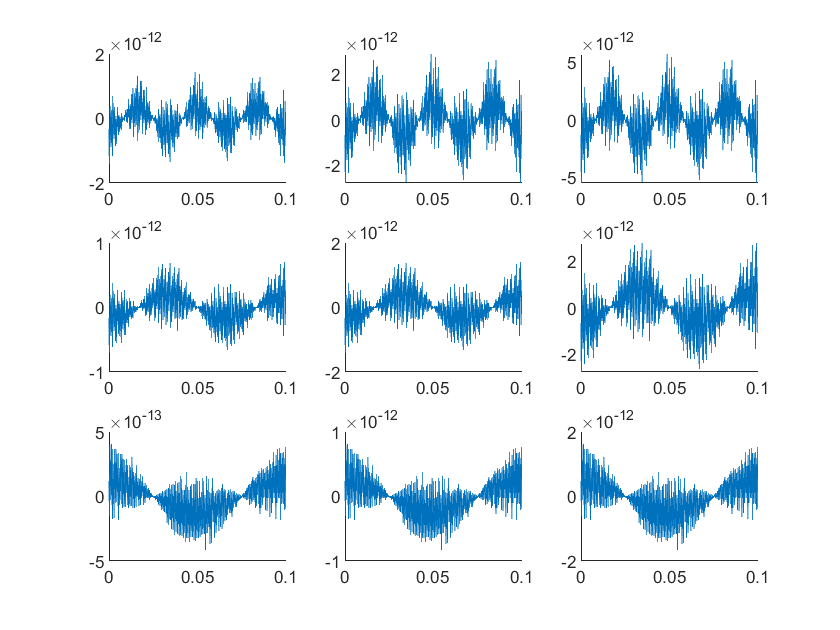

time = linspace(0,0.1,1000);
n = 5;
lambda = 1;
epsilon = 1;
I = 1;
A = lambda.*[1/4 1/2 1];
T = epsilon./[30 15 010];
d = cell(length(A),length(T));
for aa = 1:length(A)
    for tt = 1:length(T)
        d{aa,tt} = DD(time,I,A(aa),T(tt),epsilon,lambda,n);
    end
end

pp = 1;
for aa = 1:length(A)
    for tt = 1:length(T)
        subplot(3,3,pp) ; hold on
        plot(time,d{tt,aa})
        pp = pp + 1;
    end
end

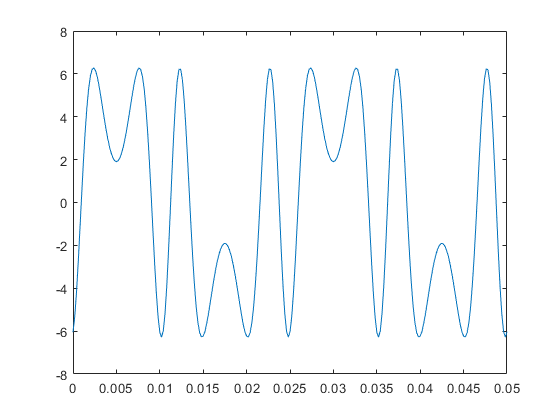

clear;close all;clc

DD =  @(t, I, A, T, epsilon, lambda, n) -(2*pi/lambda)*I^(2)*sin((2*pi/lambda).*A*(2*cos((2*pi/T)*(t-epsilon/2)).*sin(pi*epsilon/T)))*n*lambda;
time = linspace(0,2,10000);
n = 1;
lambda = 30;
epsilon = 35e-3;
I = 1;
A = 15;
T = 1/40;

test = DD(time,I,A,T,epsilon,lambda,n);


plot(time,test)
xlim([0 2*T])